# The AstSpec class

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

The `AstSpec` class is a container for astronomical spectra as well as a collection of functions to read, write, manipulate, display and analyze spectra. 

This file is accessible through the `manual` package (i.e. `manual.AstSpec`).

## Credit

If you are using this code or products in your scientific publication please give a reference to [Ofek (2014; ascl.soft 07005)](http://adsabs.harvard.edu/abs/2014ascl.soft07005O).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

## The AstSpect class properties

The `AstSpec` class have the following properties

`Wave` - Wavelength vector

`Int` - Intensity

`Err` - Error

`Back` - Background

`Mask` - Mask (inherited from the MASK class)

`WaveUnits` - Wavelength units

`IntUnits` - Intensity units

`AddCol` - Additional columns

`ObjName` - Object name

`comments` - comments

`source` - source of information

`FileName` - File name

`z` - redshift

`JD` - Julian day

`Header` - Header (inherited from the HEAD class)

`WCS` - WCS (inherited from the WorldCooSys class)

`UserData` - User data

# Methods and examples

To see all the properties and methods (functions) associated with the `AstSpec` object, first define an `AstSpec` object:

AS=AstSpec

AS =   AstSpec with properties:

         Wave: []
          Int: []
          Err: []
         Back: []
         Mask: []
    WaveUnits: []
     IntUnits: []
       AddCol: []
      ObjName: []
     comments: []
       source: []
     FileName: []
            z: []
           JD: []
       Header: {0×3 cell}
          WCS: []
     UserData: []


 and then type:

%AS.<tab>

## Read and save spectra

array2astspec, astspec2mat, astspec2struct

## Load spectra from local database

Use the static method `AstSpec.get_galspec` to load template spectra of quasars and galaxies from local database (requires the /data directory).

Note that many of these functions can also return the spectra in matrix format instead as an AstSpec object (see help of specific functions for details).

% show available templates
AstSpec.get_galspec

       Gal_Bulge.txt  : % Galaxy buldge template:  Kinney-Calzetti
           Gal_E.txt  : % Elliptical galaxy: Kinney-Calzetti
  Gal_E_Mannucci.txt  : % Elliptical galaxy spectrum (to the NIR):  Mannucci et al. 2001
          Gal_S0.txt  : % S0 galaxy:  Kinney-Calzetti
          Gal_Sa.txt  : % Sa galaxy:  Kinney-Calzetti
          Gal_Sb.txt  : % Sb galaxy:  Kinney-Calzetti
         Gal_Sbc.txt  : % Sb/Sc galaxy: Kinney-Calzetti
          Gal_Sc.txt  : % Sc galaxy: Kinney-Calzetti
  Gal_StarBurst1.txt  : % Starburst1 galaxy (E(B-V)<0.11):  Kinney-Calzetti
  Gal_StarBurst2.txt  : % Starburst2 galaxy (E(B-V)=0.11..0.21):  Kinney-Calzetti
  Gal_StarBurst3.txt  : % Staburst3 galaxy (E(B-V)=0.25..0.35): Kinney-Calzetti
  Gal_StarBurst4.txt  : % Staburst4 galaxy (E(B-V)=0.39..0.50): Kinney-Calzetti
  Gal_StarBurst5.txt  : % Staburst5 galaxy (E(B-V)=0.51..0.60): Kinney-Calzetti
  Gal_StarBurst6.txt  : % Staburst6 galaxy (E(B-V)=0.61..0.70): Kinney-Calzetti
        QSO_FBQS.txt  : % FBQS/QSO

ans =     'Gal_Bulge.txt'    'Gal_E.txt'    'Gal_E_Mannucci.txt'    'Gal_S0.txt'    'Gal_Sa.txt'    'Gal_Sb.txt'    'Gal_Sbc.txt'    'Gal_Sc.txt'    'Gal_StarBurst1.txt'    'Gal_StarBurst2.txt'    'Gal_StarBurst3.txt'    'Gal_StarBurst4.txt'    'Gal_StarBurst5.txt'    'Gal_StarBurst6.txt'    'QSO_FBQS.txt'    'QSO_FBQS_RL.txt'    'QSO_FBQS_RQ.txt'    'QSO_HBal.txt'    'QSO_LBQS.txt'    'QSO_LBal.txt'    'QSO_NIR.txt'    'QSO_SDSS.txt'


ans =   Line with properties:

              Color: [0 0.447 0.741]
          LineStyle: '-'
          LineWidth: 0.5
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×7740 double]
              YData: [1×7740 double]
              ZData: [1×0 double]

  Show all properties


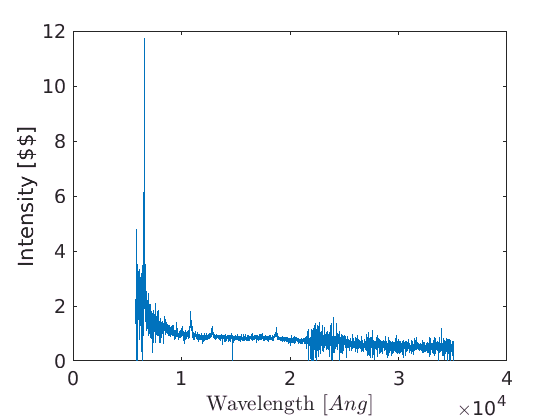

% load specific template
S=AstSpec.get_galspec('QSO_NIR');
plot(S)

The [Pickles (1998)](http://adsabs.harvard.edu/abs/1998PASP..110..863P) library of stellar spectra template is available in the data/ directory and accessible using the `AstSpec.get_pickles` static method:

% load the entire Pickles library
S=AstSpec.get_pickles
% load spectra of GV star:
S=AstSpec.get_pickles('g','v');
stairs(S);

The GAIA synthetic spectra library is available using the `AstSpec.wget_gaia_synspec `and `AstSpec.get_gaia_synspec` methods. The first retrieve the spectra from the web, whilethe later bring it from the local /data directory.

S=AstSpec.get_gaia_synspec(5000,0,0,0);
plot(S)

## Calculate special spectra

Use the AstSpec.blackbody method to genertae a blackbody spectra:

% BB spectra at 5000K and 10000K
AstS=AstSpec.blackbody([5000;10000]);
plot(AstS);
set(gca,'YS','log','XS','log')
% More options
WaveRange = (2000:100:10000)';
AstS=blackbody(5000,WaveRange,'ph/A'); % spectra units photons/Ang

The zodiacal spectra (and background) is available via the `AstSpec.zodiac_spectrum`, and `AstSpec.zodiac_bck` functions:

plot(AstSpec.zodiac_spectrum);

## Plot spectra

To plots the content of an `AstSpec` object use the `plot`, `plotf`, `stairs`, `stairsf`, `plot_labels` functions.

## Interpolation and sampling

The `interp` method can be used to interpolate all the spectra in an `AstSpec` object into a new grid:

S=AstSpec.get_pickles;
W=(5000:10:6000)';
S=interp(S,W);
plot(S(1:3))

The `resample` method can be used to resample all the spectra in `AstSpec` class linearly or logarithmically. For example, logarithmic scaling is required for cross-correlation (i.e., redshift is linear in logspace).

S=resample(S,'log')

## Arithmetic operations

Arithmatic operations between two spectra that have identical sampling:

S=AstSpec.get_pickles;
S=interp(S,S(1).Wave);
arith(S,S(1),@minus);   % subtract the first spectra from all the spectra

In addition, astspec_fun1 and astspec_fun2 can be used to run a unary and binary function of AstSpec field and write the result to the field:

S=AstSpec.get_pickles;
% add the intensity in S(1:2) to that in S(1)
AstS=astspec_fun2(S(1:2),S(1),'Int',@plus);
% calculate the sin of all the fields
AstS=astspec_fun1(S(1:3),'all',@sin);
% calculate the sin of all fields except wavelength
AstS=astspec_fun1(S(1:3),'notwave',@sin);

## Scalar operations

The `fun_scalar` method can be used to apply a function that get a vector and return a scalar (e.g., `@mean`):

S=AstSpec.get_pickles;
Mean = S.fun_scalar(@mean)

Some basic functions are overloaded and can be used directly:

S=AstSpec.get_pickles;
mean(S);
median(S);
integral(S);  % Calculate the integral of the spectrum

## Synthetic photometry

Synthetic photometry of spectra can be calculated using synphot. Note that synphot can work also on spectra in two column matrix format:

S=AstSpec.get_pickles;   % load all the Pickles library spectra
% calculate synthetic photometry in the SDSS r-band in AB magnitude
[Mag,Flag,EffW]=synphot(S,'SDSS','r','AB');
% Divide all the spectra such that their r-band mag will be -20
S1=arith(S,10.^(0.4.*(Mag-(-20))),@times);
plot(S(1));
hold on;
plot(S1(1))

## Filtering spectra

The following functions and overload methods are available for filtering-related operations: `medfilt1`, `hampel`, `sgolayfilt`, `convolve`, `filter`, `filter_lines`, `stdfilt1`, `errfilt1`, `fft`, `ifft`, `fftshift`, `ifftshift`, `conj`, `abs`, `real`, `imag`.

Examples:

S=AstSpec.get_pickles('g','v');
S=S(1); % not necessery for the example
plot(S);
hold on;
Sm = medfilt1(S,10);
plot(Sm)
hold on;
% filter_lines identify and remove spectral lines
Sl = filter_lines(S)
plot(Sl)
legend('Original','medfilt1','filter\_lines')
% zoom in on one line to see how it works:
axis([6000 7000 0.6 0.9]);

## Fitting operations

Several fitting functions are available, including `fit_bb` (fit black body spectra).

TBD - integrate fit_lines.m.

Black body fitting example:

S=AstSpec.get_pickles('g','v');
S=S(1); % not necessery for the example
% plot original spectrum
plot(S);
hold on;
% remove spectral lines
S = filter_lines(S);
plot(S);
hold on;
[Fit,Sbb]=fit_bb(S);
hold on;
% overlay the BB spectrum
plot(Sbb)
% show fit results
Fit

## Cross correlation

TBD

## The Header

The `AstSpec` object contain an header field which henerite from the [HEAD class](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/HEAD.html), and all the `HEAD` class methods are available. This is including header manipulation, queries, and world coordinate system.